# Interpolation of Complex Values

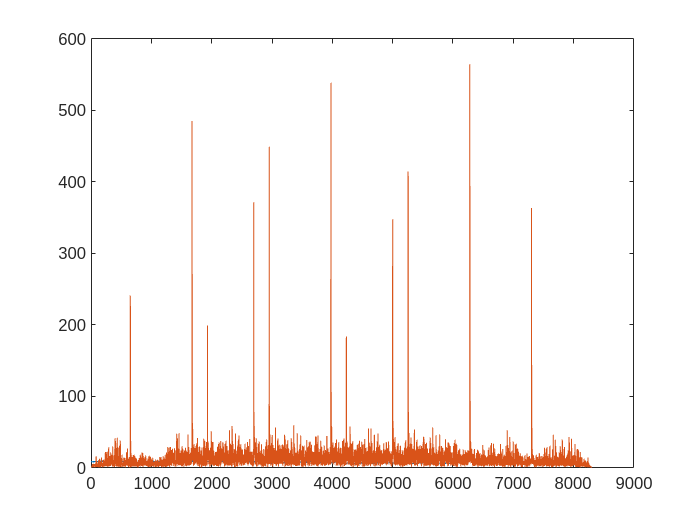

clc;clear;
load("/home/dellx/文档/uhd/host/Simulation_RU/Simulation_RU/heltf160_x2.mat")
data = read_complex_binary('/mnt/tmp/downsamp__1003_x2_withCP_breathe2.dat'); 


i = 4;
% symbollen_table = [288, 576, 1152, 2304];
symbollen_table = [256, 512, 1024, 2304];
gilen_table = [32, 64, 128, 256];
symbollen = symbollen_table(i);
gilen = gilen_table(i);
data1 = [data(3977-256:end); zeros(symbollen - mod(length(data(3977-256:end)), symbollen), 1)];
data1 = reshape(data1, [symbollen, length(data1) / symbollen]);


cfr_all=fftshift(fft(data1(cfg.gilen+1:end,:)));
cir=ifft(fftshift(cfr_all.*conj(cfg.userltf(1,:)'))); %convolution
corr_result = conv(data(1:6000), bb(1,1:end));
plot(abs(corr_result))
hold on

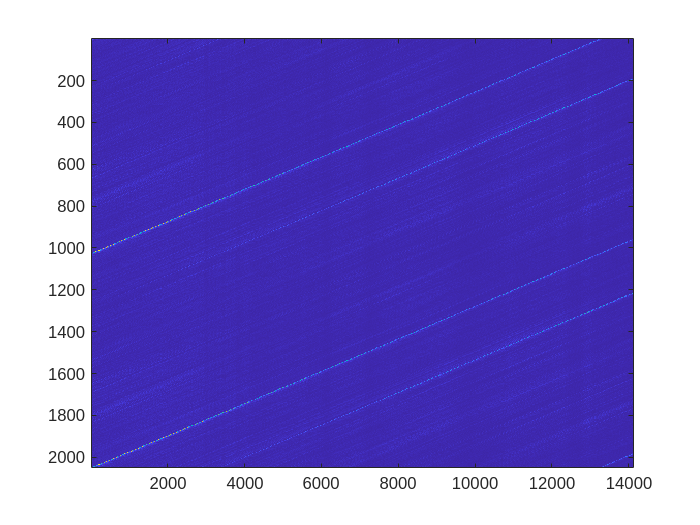

figure
imagesc(abs(cir(:,:)))
% ylim([511 517])
hold on% xlim([1 500])

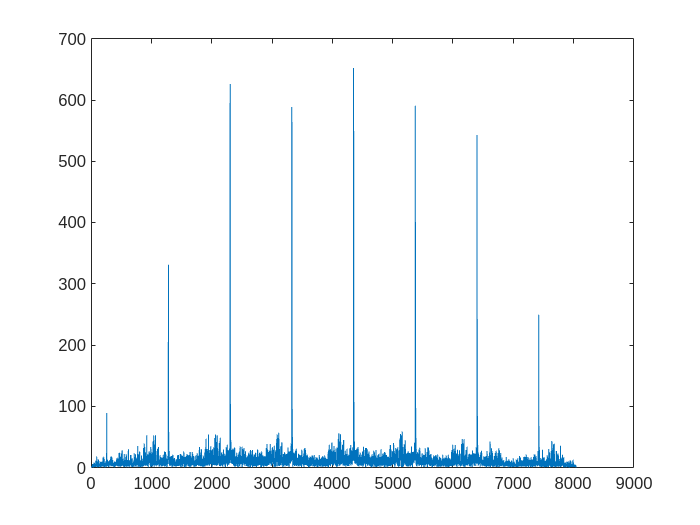

cfr_all=fftshift(fft(data1(257:end, :)));

theta_initial = unwrap(angle(cfr_all(:,:)),[], 2);
tx = cfg.userltf(1,:)';
temp = cfr_all.*conj(tx);
theta_temp = unwrap(angle(temp(:,:)),[], 2);
theta_temp_diff = diff(theta_temp, 1, 2);

theta_k_mean = mean(theta_temp_diff,2);
i = 1:length(cfr_all);
theta_ik = theta_k_mean * i;
% theta_compen = 2*pi/20/2048*(-1023:1024);
cfr = cfr_all .* exp(-1j * theta_ik);
cir2=ifft(fftshift(cfr.*conj(cfg.userltf(1,:)'))); %convolution
[~,pos2] = max(abs(cir2));

data2 = ifft(fftshift(cfr_all));
figure
corr_result = conv(data2(1:6000), bb(1,1:end-256));
% % corr_result = [corr_result; zeros(symbollen - mod(length(corr_result), symbollen), 1)]; 
% % corr_result2 = reshape(corr_result, [symbollen, length(corr_result) / symbollen]);
plot(abs(corr_result))
hold on

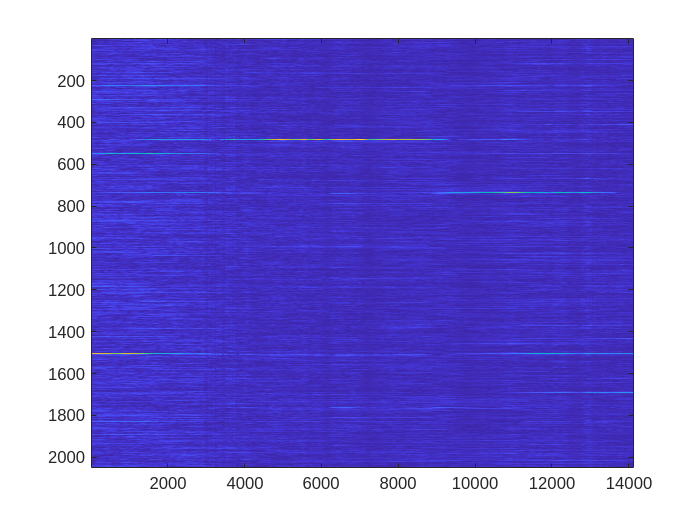

% data2 = reshape(data2(769-256:end),[],1);
% data3 = [data2(1:end); zeros(symbollen - mod(length(data2(1:end)), symbollen), 1)];
% data3 = reshape(data3, [symbollen, length(data3) / symbollen]);
% % 
% % usrp_160_0719_breathe1.dat
% cfr3=fftshift(fft(data3(257:end, :)));
% cir3=ifft(fftshift(cfr3.*conj(cfg.userltf(1,:)'))); %convolution

figure
imagesc(abs(cir2(:,:)))
% ylim([511 517])
hold on% xlim([1 500])

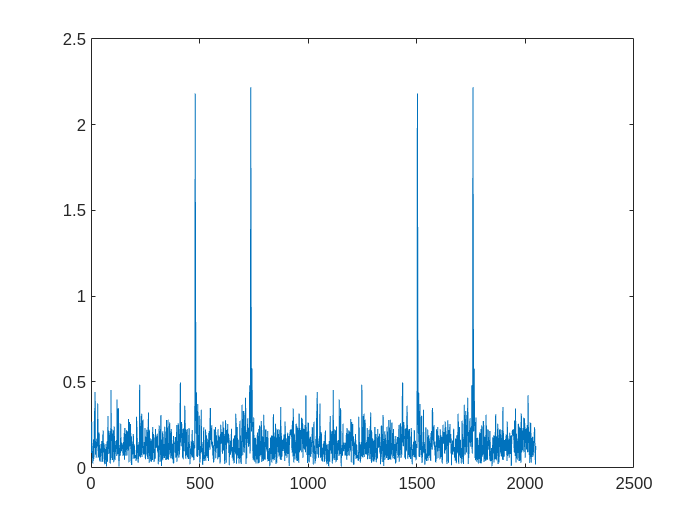

figure
plot(abs(cir2(:,10000)))
hold on

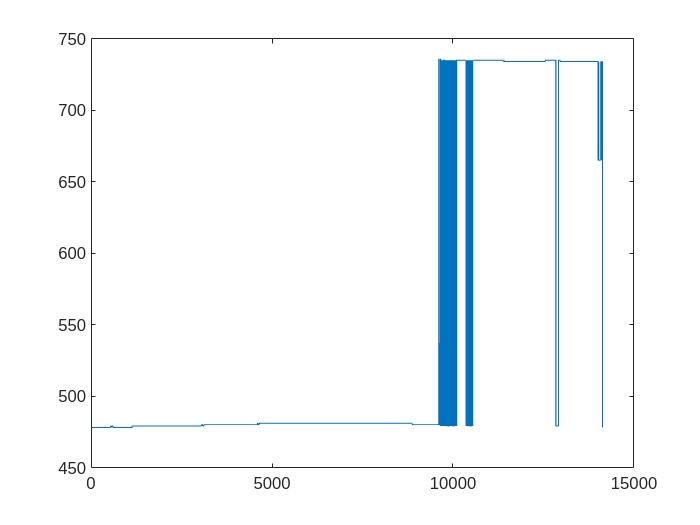

错误使用 hold
命令选项必须为 'on' 或 'off'。

figure
plot(pos2)
hold on1

figure
plot(abs(cir(644,:)))
hold on

N = 30

N = 30

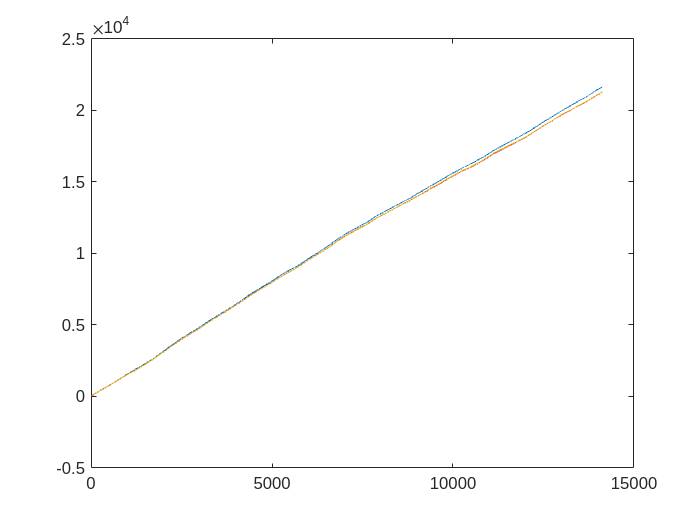

figure
plot(theta_temp(13,:));
hold on
plot(theta_temp(17,:));
hold on
plot(theta_temp(21,:));
hold on

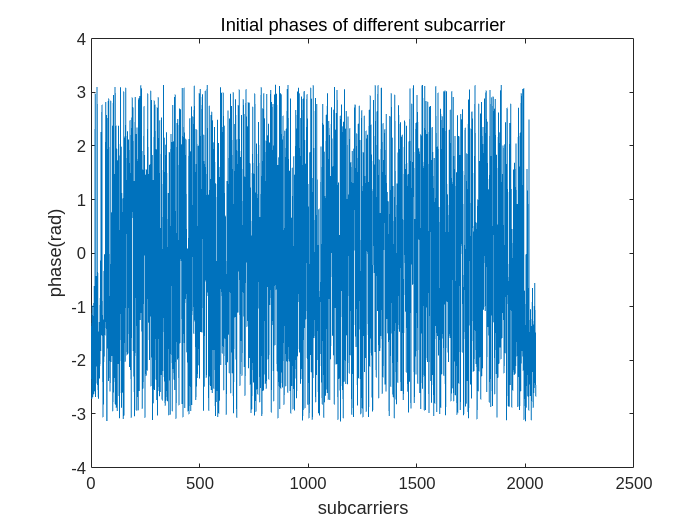

% for i = 2:N
% theta_temp_new(:,i) = theta_temp(:,i) - theta_compen';
% end
% theta_unwarp = unwrap(theta_temp);
figure
plot(theta_initial(:,1));
hold on
title('Initial phases of different subcarrier')
ylabel('phase(rad)')
xlabel('subcarriers')

figure
t = theta_temp(:,6900);
t(t==0) = [];0

ans = 0

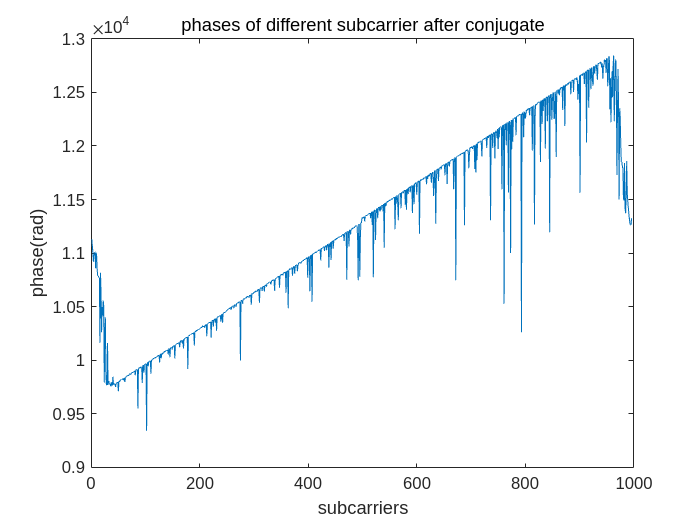

plot(t(:,1));
hold on
title('phases of different subcarrier after conjugate')
ylabel('phase(rad)')
xlabel('subcarriers')

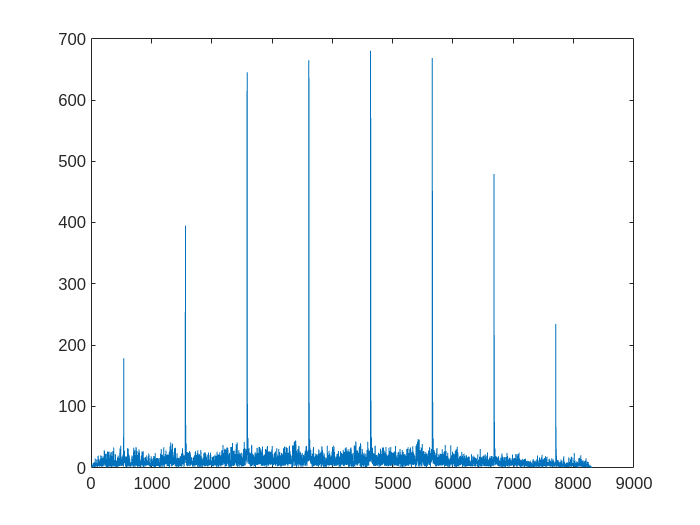

figure
corr_result = conv(data2(1:6000), bb(1,1:end));
% corr_result = [corr_result; zeros(symbollen - mod(length(corr_result), symbollen), 1)]; 
% corr_result2 = reshape(corr_result, [symbollen, length(corr_result) / symbollen]);
plot(abs(corr_result))
hold on

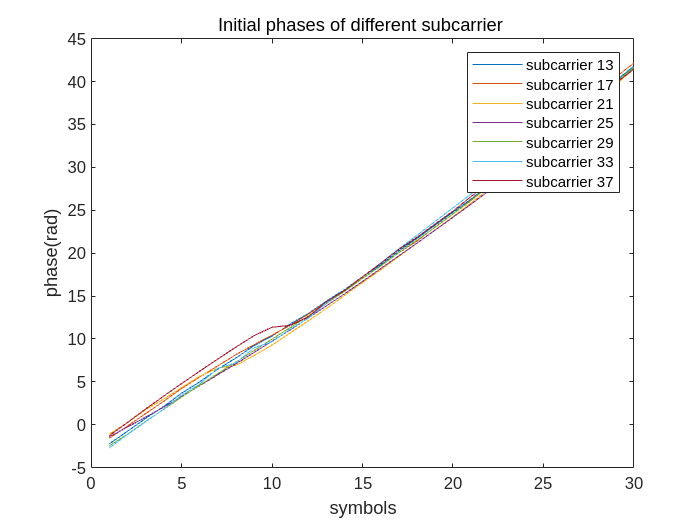


figure
plot(theta_initial(13,1:N));
hold on
plot(theta_initial(17,1:N));
hold on
plot(theta_initial(21,1:N));
hold on
plot(theta_initial(25,1:N));
hold on
plot(theta_initial(29,1:N));
hold on
plot(theta_initial(33,1:N));
hold on
plot(theta_initial(37,1:N));
hold on
title('Initial phases of different subcarrier ')
legend('subcarrier 13', 'subcarrier 17', 'subcarrier 21', 'subcarrier 25', 'subcarrier 29', 'subcarrier 33', 'subcarrier 37')
ylabel('phase(rad)')
xlabel('symbols')

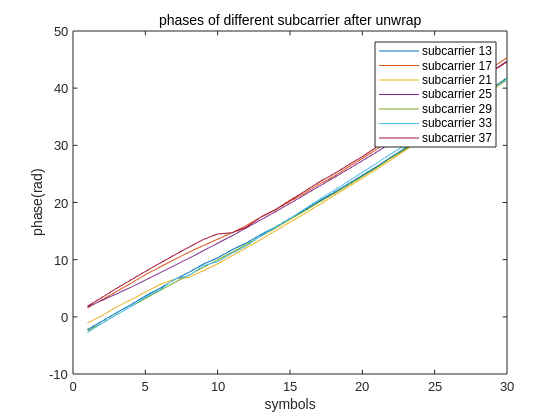



figure
plot(theta_temp(13,1:N));
hold on
plot(theta_temp(17,1:N));
hold on
plot(theta_temp(21,1:N));
hold on
plot(theta_temp(25,1:N));
hold on
plot(theta_temp(29,1:N));
hold on
plot(theta_temp(33,1:N));
hold on
plot(theta_temp(37,1:N));
hold on
title('phases of different subcarrier after unwrap')
legend('subcarrier 13', 'subcarrier 17', 'subcarrier 21', 'subcarrier 25', 'subcarrier 29', 'subcarrier 33', 'subcarrier 37')
ylabel('phase(rad)')
xlabel('symbols')

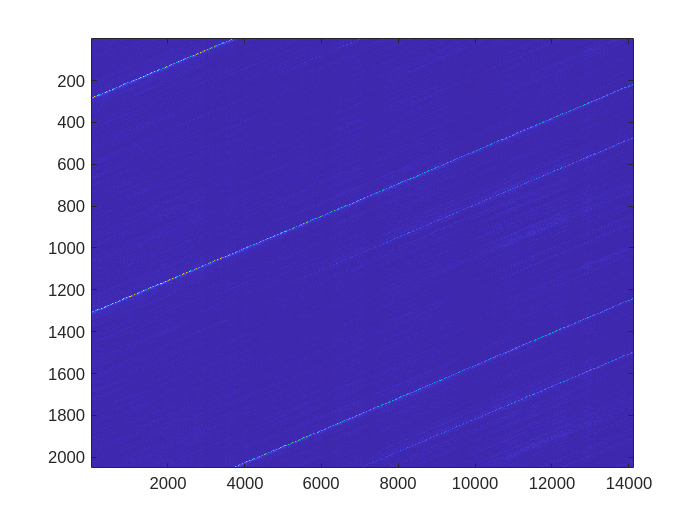

cir=ifft(fftshift(cfr_all.*conj(cfg.userltf(1,:))')); %convolution
% figure
% plot(abs(cir(1:2048*6000)))
% hold on
[I1,pos1] = max(cir);
figure
imagesc(abs(cir(:,:)))
% ylim([511 517])
hold on% xlim([1 500])

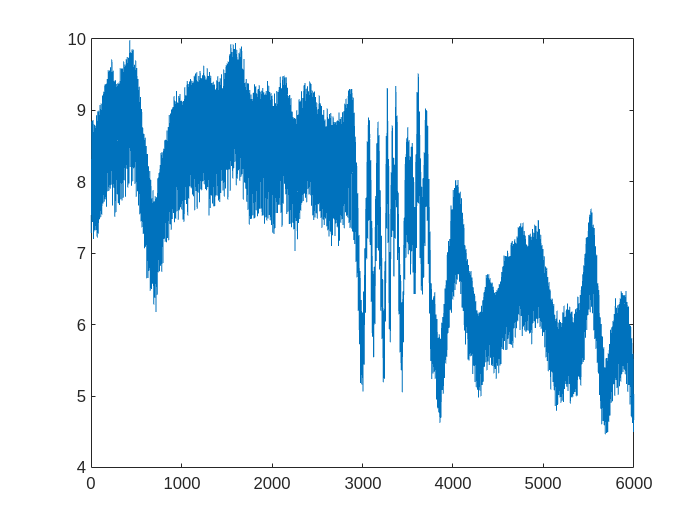



figure
plot(abs(I1(1:6000)))
hold on

data1 = reshape(data1, [symbollen, length(data1) / symbollen]);

错误使用 reshape
大小参数必须为整型实数。

bias = 1 - (first_index - last_index) * 1.0 / (length(data1) * length(data1(:,1)));
data3 = zeros(size(data1));
% for i = 1:length(data1)-1
%     raw_x = linspace(i * symbollen, (i+1) * symbollen + 1, (symbollen + 2)) * bias;
%     new_x = ceil(i * symbollen * bias): floor(((i+1)*symbollen+1) * bias + 1);
%     gi_new_x = floor(new_x(1)/symbollen);
%     if gi_new_x * symbollen < new_x(1)
%         gi_new_x = gi_new_x + 1;
%     end
%     raw_y = cat(1, data1(:,i), data1(1:2,i+1));
% %     f = interp1(raw_x, raw_y);
% %     new_y = f(new_x(:symbollen))
%     new_y = interp1(raw_x, raw_y, new_x(1:symbollen),'cubic');
%     gi_shift = round(gi_new_x * symbollen - new_x(1));
%     if gi_shift == 0
%        data3(:,i) = new_y;
%     else
%         data3(1:1+end-gi_shift,i) = new_y(gi_shift:end);
%         data3(end-gi_shift+1:end, i) = new_y(1:gi_shift);

%     end
% end
N = length(cfr_all);

figure
plot(real(data(1:10000)))
hold on
plot(imag(data(1:10000)))
hold on


figure
plot(pos1(1:5000))
hold on
% 0718 shiyu%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
first_index = pos1(1);
last_index = pos1(end);
offset = first_index
data1 = [data; zeros(symbollen - mod(length(data), symbollen), 1)];
data1 = reshape(data1, [symbollen, length(data1) / symbollen]);
bias = 1 - (first_index - last_index) * 1.0 / (length(data1) * length(data1(:,1)));
data3 = zeros(size(data1));
for i = 1:length(data1)-1
    raw_x = linspace(i * symbollen, (i+1) * symbollen + 1, (symbollen + 2)) * bias;
    new_x = ceil(i * symbollen * bias): floor(((i+1)*symbollen+1) * bias + 1);
    gi_new_x = floor(new_x(1)/symbollen);
    if gi_new_x * symbollen < new_x(1)
        gi_new_x = gi_new_x + 1;
    end
    raw_y = cat(1, data1(:,i), data1(1:2,i+1));
%     f = interp1(raw_x, raw_y);
%     new_y = f(new_x(:symbollen))
    new_y = interp1(raw_x, raw_y, new_x(1:symbollen),'cubic');
    gi_shift = round(gi_new_x * symbollen - new_x(1));
    if gi_shift == 0
       data3(:,i) = new_y;
    else
        data3(1:1+end-gi_shift,i) = new_y(gi_shift:end);
        data3(end-gi_shift+1:end, i) = new_y(1:gi_shift);
    end
end


% 0718 shiyu%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


for i = 1:size(cir,2)
    a(i) = floor((i-1)*atan(0.08));
    cir1 = circshift(cir(:,i),a(i),1);
end
figure
imagesc(abs(cir(:,:)))
% ylim([511 517])
hold on% xlim([1 5

figure
plot(pos1(1:5000))
hold on
% for i = 1:1000
% cir(:,i) = circshift(cir(:,i),round(i * 0.09));
% end
% figure
% imagesc(abs(cir))
% ylim([511 517])
% hold on% xlim([1 500])/11-
theta = angle(cir(:,:));
theta_diff = [zeros(2048,1),diff(theta, 1, 2)];
theta_unwrap = unwrap(theta, 0, 2);
figure
for i = 2040:2048
plot(theta_unwrap(i,:))
hold on
end
legend()


pos1(end-2:end) = pos1(end-3);
start = pos1+256 + (0:length(pos1) - 1) * 2304;
finish = start + 2047;

data_useful = zeros(2048, length(data1)-5);

for i = 1:1:length(data_useful)-5
data_useful(:,i) = data(start(i):finish(i));
end

cfr_all=fftshift(fft(data_useful(1:end,:)));
cir=ifft(fftshift(cfr_all.*conj(cfg.userltf(1,:)'))); %convolution
[~,pos] = max(cir);

figure
plot(pos(1:5000))
hold on

figure
imagesc(abs(cir))
ylim([511 517])
hold on
figure
imagesc(abs(diff(cir, 1, 2)))
hold on
figure
plot(abs(cir(512,:)))
hold on
% plot(abs(MovingAverageFilter(cir(512,:),100)))   
% hold on
figure
plot(abs(cir(513,:)))
hold on
% plot(3*abs(lowpass(cir(513,:),150,200e6)))   
% hold on
figure
plot(abs(cir(514,:)))
hold on
% plot(3*abs(lowpass(cir(514,:),150,200e6)))   
% hold on
figure
plot(abs(cir(515,:)))
hold on

figure
plot(abs(cir(516,:)))
hold on

figure
plot(abs(cir(517,:)))
hold on

% cfr_all=fftshift(fft(data1(257:end,:)));
% cir=ifft(fftshift(cfr_all.*conj(cfg.userltf(1,:)'))); %convolution
theta = angle(cir(:,:));
theta_diff = [zeros(2048,1),diff(theta, 1, 2)];
theta_unwrap = unwrap(theta, 0, 2);
% figure
% for i = 1:2048
% plot(theta_unwrap(i,:));
% hold on
% end

slope = zeros(2048,1);
for i = 1:2048
mdl = fitlm(1:length(theta_unwrap),theta_unwrap(i,:));
slope(i,:) = mdl.Coefficients.Estimate(2);  % the coefficients
end
% figure
% plot(slope)
% hold on
slope_dif = slope - slope(1024);

figure
plot(slope_dif)
hold on

% SFO compensation
t = 1:N-5;
SFO_theta = t .* slope_dif;
cir_sfo = cir(:,:) .* exp(-1j * SFO_theta);
theta = angle(cir_sfo(:,:));
theta_unwrap_sfo = unwrap(theta, 0, 2);
% figure
% for i = 1:2048
% plot(theta_unwrap_sfo(i,:));
% hold on
% end

% CFO compensation
slope2 = zeros(2048,1);
for i = 1:2048
mdl = fitlm(1:length(theta_unwrap_sfo),theta_unwrap_sfo(i,:));
slope2(i,:) = mdl.Coefficients.Estimate(2);  % the coefficients
end
max(slope2)-min(slope2)
mean(slope2)
CFO_theta = theta(513,:);
% t = 1:N-5;
% CFO_theta = t .* mean(slope2);
cir_cfo = cir_sfo(:,:) .* exp(-1j  * CFO_theta);
theta_cfo = angle(cir_cfo(:,:));
theta_unwrap_cfo = unwrap(theta_cfo, 0, 2);
% figure
% for i = 1:2048
% plot(theta_unwrap_cfo(i,:));
% hold on
% end

[~,pos] = max(cir_sfo);
figure
imagesc(abs(cir_sfo))
ylim([511 517])
hold on
title('After SFO compensation')


% cir_cfo=ifft(fftshift(cfr_cfo.*conj(cfg.userltf(1,:)'))); %convolution
[~,pos] = max(cir_sfo);
figure
imagesc(abs(cir))
ylim([511 517])
hold on
title('After CFO compensation')

% 
% cir_dif = diff(cir, 1, 2);
% figure
% imagesc(abs(cir_dif))
% ylim([511 517])
% hold on

% % Calculate the phases of every Rx pilot tone% Calculate the phases of every Rx pilot tone
% pilot_phases = unwrap(angle(fftshift(cfr_all(513,:))), [], 1);
% 
% % Calculate slope of pilot tone phases vs frequency in each OFDM symbol
% % pilot_diff = diff(pilot_phases);
% pilot_slope_mat = mean(diff(pilot_phases));
% 
% % Calculate the SFO correction phases for each OFDM symbol
% pilot_phase_sfo_corr = fftshift((-1024:1023).' * pilot_slope_mat, 1);
% pilot_phase_corr = exp(-1i*(pilot_phase_sfo_corr));
% 
% % Apply the pilot phase correction per symbol
% cfr_all = cfr_all .* pilot_phase_corr;
% cir=ifft(fftshift(cfr_all.*conj(cfg.userltf(1,:)'))); %convolution
% 
% figure
% plot(pos1)
% hold on
% 
% figure
% imagesc(abs(cir))
% ylim([511 517])
% hold on
% mdl_1 = fitlm(1:342,pos1(1:342))
% mdf_2 = fitlm(1:5700, pos1(343:6042))
% mdl_3 = fitlm(1:871, pos1(6043:end))
% v = 0:-1:-30;
% del = repelem(v,11);
% del(:,1:7) = []
% pos2 = 31 + del;
% 
% M = movmean(pos1(1:340),11);

% pos2 = round(30.955 - 0.08856 * (1:340));
% pos3 = round(514 - 0.09 * (1:5700));
% pos4 = round(512.5 - 0.09 * (1:871));
% 
% n = length(data1)
% pos_n = round(31 - 0.09 * (1:n-3));
% 
% start = pos_n+256 + (0:n-4) * 2304;
% finish = start + 2047;
% 
% data_useful = zeros(2048, n-3);
% 
% for i = 1:1:n-3
% data_useful(:,i) = data(start(i):finish(i));
% end
% 
% cfr_all=fftshift(fft(data_useful(1:end,:)));
% cir=ifft(fftshift(cfr_all.*conj(cfg.userltf(1,:)'))); %convolution
% [~,pos] = max(cir);
% figure
% imagesc(abs(cir(511:516,:)))
% % xlim([1 500])
% hold on



% % 
% % figure
% % plot(abs(cir(1:2048*4340)));   
% % hold on
% 
% data1 = [data; zeros(symbollen - mod(length(data), symbollen), 1)];
% data1 = reshape(data1, [symbollen, length(data1) / symbollen]);
% 
% num = 2048;
% pos_diff = -621;
% 
% data_use = data1(257:end,:);
% data_after_itv = zeros(2048,length(data1));
% 
% delta = pos_diff/43403;
% xq = 1 : 1+delta : 1+2047*(1+delta);
% data_after_itv(:,:) = interp1(data_use(:,:),xq);
% 
% % figure
% % plot((1:num),real(data_itv(3:end,1)),'o',xq,real(dataq(:,1)),'*');
% % legend('v','vq');
% cfr_all=fftshift(fft(data_after_itv(1:end, :)));
% cir=ifft(fftshift(cfr_all.*conj(cfg.userltf(1,:)'))); %convolution
% [I2,pos2] = max(cir);
% 
% figure
% imagesc(abs(cir))
% xlim([1 5000])
% hold on

% plot(imag(data_itv),'*b');

% 
% cfr_all=fftshift(fft(data1(cfg.gilen+1:end, :)));
% cir=ifft(fftshift(cfr_all.*conj(cfg.userltf(1,:)'))); %convolution
% 
% figure
% plot(abs(cir))
% hold on

*Copyright 2015 The MathWorks, Inc.*